% 3.19
clear
syms U1 U2
U=U1+U2

$$U = U_{1}+U_{2}$$

syms R1 R2 omega  L1 L2 M I
U1=(R1+1j*omega*L1)*I+1j*omega*M*I

$$U1 = \text{I}\,\left(R_{1}+L_{1}\,\omega \,\mathrm{i}\right)+\text{I}\,M\,\omega \,\mathrm{i}$$

U2=(R2+1j*omega*L2)*I+1j*omega*M*I

$$U2 = \text{I}\,\left(R_{2}+L_{2}\,\omega \,\mathrm{i}\right)+\text{I}\,M\,\omega \,\mathrm{i}$$

U=U1+U2

$$U = \text{I}\,\left(R_{1}+L_{1}\,\omega \,\mathrm{i}\right)+\text{I}\,\left(R_{2}+L_{2}\,\omega \,\mathrm{i}\right)+2\,\text{I}\,M\,\omega \,\mathrm{i}$$

U=((R1+R2)+1j*omega*(L1+L2+2*M))*I

$$U = \text{I}\,\left(R_{1}+R_{2}+\omega \,\left(L_{1}+L_{2}+2\,M\right)\,\mathrm{i}\right)$$

syms Z_E
U=Z_E*I

$$U = \text{I}\,Z_{E}$$

Z_E==(R1+R2)+1j*omega*(L1+L2+2*M)

$$ans = Z_{E}=R_{1}+R_{2}+\omega \,\left(L_{1}+L_{2}+2\,M\right)\,\mathrm{i}$$

syms R_E L_E
Z_E==R_E+1j*omega*L_E

$$ans = Z_{E}=R_{E}+L_{E}\,\omega \,\mathrm{i}$$

% При согласном включении
Z_E=(R1+R2)+1j*omega*(L1+L2+2*M)

$$Z\_E = R_{1}+R_{2}+\omega \,\left(L_{1}+L_{2}+2\,M\right)\,\mathrm{i}$$

% При встречном вкючении
Z_E=(R1+R2)+1j*omega*(L1+L2-2*M)

$$Z\_E = R_{1}+R_{2}+\omega \,\left(L_{1}+L_{2}-2\,M\right)\,\mathrm{i}$$

syms X_Lsogl X_Lvstr X_L1 X_L2 X_M
X_Lsogl=X_L1+X_L2+2*X_M, X_Lvstr=X_L1+X_L2-2*X_M

$$X\_Lsogl = X_{\mathrm{L1}}+X_{\mathrm{L2}}+2\,X_{M}$$

$$X\_Lvstr = X_{\mathrm{L1}}+X_{\mathrm{L2}}-2\,X_{M}$$

% При всех условиях
X_L1+X_L2+2*X_M>0, L1+L2>=2*M

$$ans = 0<X_{\mathrm{L1}}+X_{\mathrm{L2}}+2\,X_{M}$$

$$ans = 2\,M\leq L_{1}+L_{2}$$

% 3.20

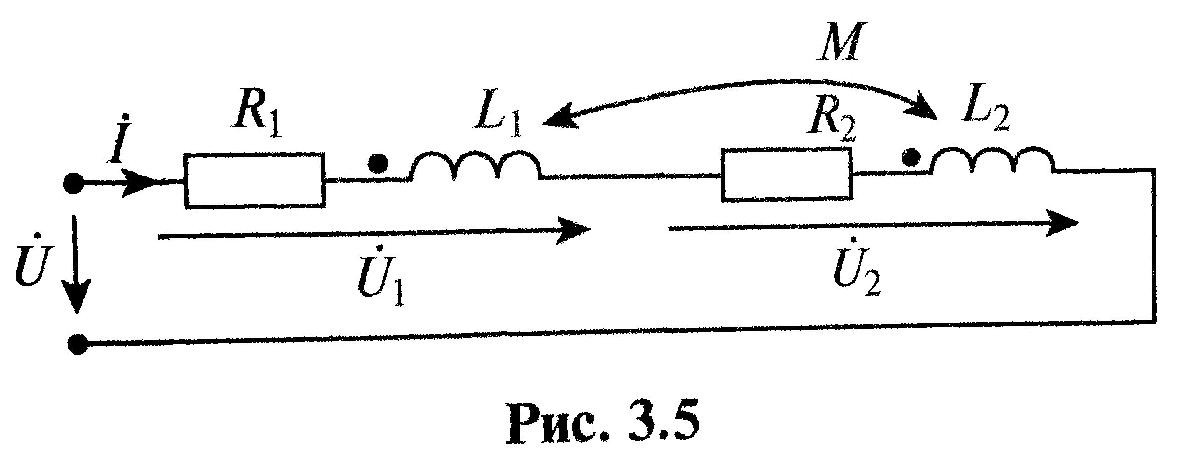

clear
X1=20 % Ом

X1 = 20

X2=30 % Ом

X2 = 30

X_M=5 % Ом

X_M = 5

R1=0, R2=0

R1 = 0

R2 = 0

U=120 % В

U = 120

% I,U1,U2 -? при согл и встр подкл

% При согласном включении:
% а) полное сопротивление цепи
z_Esogl=X1+X2+2*X_M

z_Esogl = 60

% б) действующее значение тока
I_sogl=U/z_Esogl

I_sogl = 2

% в) действующее значение напряжения на 1-й катушке
% U1=I_sogl*z_1sogl
% где z_1sogl=X1+X_M
U1=I_sogl*(X1+X_M)

U1 = 50

% г) действующее значение напряжения на 2-й катушке
% U2=I_sogl*z_2sogl
% где z_2sogl=X2+X_M
U2=I_sogl*(X2+X_M)

U2 = 70


% При встречном включении:
% а) полное сопротивление цепи
z_Evstr=X1+X2-2*X_M

z_Evstr = 40

% б) действующее значение тока
I_vstr=U/z_Evstr

I_vstr = 3

% в) действующее значение напряжения на 1-й катушке
% U1=I_vstr*z_1vstr
% где z_1vstr=X1-X_M
U1=I_vstr*(X1-X_M)

U1 = 45

% г) действующее значение напряжения на 2-й катушке
% U2=I_vstr*z_2vstr
% где z_2vstr=X2-X_M
U2=I_vstr*(X2-X_M)

U2 = 75

% 3.21
clear
R1=0, R2=0

R1 = 0

R2 = 0

U=120 % В

U = 120

I_sogl=2 % А

I_sogl = 2

I_vstr=6 % А

I_vstr = 6

% M-?

syms X1 X2 X_M
z_sogl=X1+X2+2*X_M

$$z\_sogl = X_{1}+X_{2}+2\,X_{M}$$

z_vstr=X1+X2-2*X_M

$$z\_vstr = X_{1}+X_{2}-2\,X_{M}$$

z_sogl-z_vstr

$$ans = 4\,X_{M}$$

z_sogl=U/I_sogl

z_sogl = 60

z_vstr=U/I_vstr

z_vstr = 20

X_M=(z_sogl-z_vstr)/4

X_M = 10

% 3.22
clear
X1=3 % Ом

X1 = 3

X2=2 % Ом

X2 = 2

X_M=1 % Ом

X_M = 1

R1=0

R1 = 0

R2=0

R2 = 0

U=10 % В

U = 10

% I,I1,I2 -? при встречном включении

syms U X1 X2 X_M I1 I2
eq1=U==X1*I1-X_M*I2

$$eq1 = U=I_{1}\,X_{1}-I_{2}\,X_{M}$$

eq2=U==-X_M*I1+X2*I2

$$eq2 = U=I_{2}\,X_{2}-I_{1}\,X_{M}$$

slv=solve(eq1,eq2,[I1 I2])

slv = struct with fields:
    I1: [1×1 sym]
    I2: [1×1 sym]


I1=slv.I1

$$I1 = \frac{U\,\left(X_{2}+X_{M}\right)}{X_{1}\,X_{2}-{X_{M}}^{2}}$$

I2=slv.I2

$$I2 = \frac{U\,\left(X_{1}+X_{M}\right)}{X_{1}\,X_{2}-{X_{M}}^{2}}$$

I1=subs(I1,[U X1 X2 X_M],[10 3 2 1])

$$I1 = 6$$

I2=subs(I2,[U X1 X2 X_M],[10 3 2 1])

$$I2 = 8$$

I=I1+I2

$$I = 14$$

% 3.23
clear
f=500 % Гц

f = 500

I1=10 % А

I1 = 10

U2=50 % В

U2 = 50

% M-?

R1=0, R2=0

R1 = 0

R2 = 0

syms U1 U2 I1 X1 X_M
eq1=U1==I1*X1

$$eq1 = U_{1}=I_{1}\,X_{1}$$

eq2=0==I1*X_M+U2

$$eq2 = 0=U_{2}+I_{1}\,X_{M}$$

% где
syms L1 L2 M omega
X1==omega*L1, X_M==omega*M

$$ans = X_{1}=L_{1}\,\omega$$

$$ans = X_{M}=M\,\omega$$

X_M1=solve(eq2,X_M)

$$X\_M1 = -\frac{U_{2}}{I_{1}}$$

X_M=U2/I1

$$X\_M = \frac{U_{2}}{I_{1}}$$

M=X_M/omega

$$M = \frac{U_{2}}{I_{1}\,\omega }$$

digits(3)
M=vpa(subs(M,[U2 I1 omega],[50 10 2*pi*500]))

$$M = 0.00159$$

% 3.24
% 4.

% 3.25
clear
U=100, X1=10, X2=20, X_M=10

U = 100

X1 = 10

X2 = 20

X_M = 10

I=U/(X1+X2-2*X_M)

I = 10

% 1.

% 3.26
clear
X1=30, X2=50, X_M=10

X1 = 30

X2 = 50

X_M = 10

X_E=X1+X2+2*X_M

X_E = 100

% 1.

% 3.27
clear
syms t Psi_L2(t)
e=-diff(Psi_L2)

$$e(t) = -\frac{\partial }{\partial t}\Psi_{\mathrm{L2}}\left(t\right)$$

% 3.

% 3.28
U=120, X1=30, X2=50, X_M=10

U = 120

X1 = 30

X2 = 50

X_M = 10

I=U/(X1+X2-2*X_M)

I = 2

U1=I*(X1-X_M)

U1 = 40

% 1.  прав.3.- 60 -?